clear all
clc

Problem 1

R = 5;
C = 0.25;
L = 1;

A = [-R/L -1/L;
    1/C 0];

[V,D] = eig(A);

Cs = [0 1];

Ob = obsv(A,Cs);

rank(Ob);

problem 2

%% MAE 6760 Model Based Estimation
%
%   Homework #1
%   problem #2: Multivariate Gaussian Random Variable
%        application: localization of a phone
%

%Upson 206 "true" Lat-Lon location
x_true=[ 42.44396; %deg
        -76.48248];%deg

Re=6378100; %radius of the Earth in m

%3D position in LLA coordinates
x_lla=[42.44445; %deg
      -76.48252; %deg
            263];%m
%3D covariance position in units of m^2
P_llam = [400 40 100;
          40 400 100;
          100 100 2500]; 

P = [400 40; 40 400];

x_hat = [42.44445;-76.48252];

rank(P);
%conversion for Lat-Lon angular error to error in m
%assumes small angles
convert_LLerr2merr = pi/180*Re; 


e_deg = x_true - x_hat;
e_m = convert_LLerr2merr*e_deg

e_m =   -54.5462
    4.4528


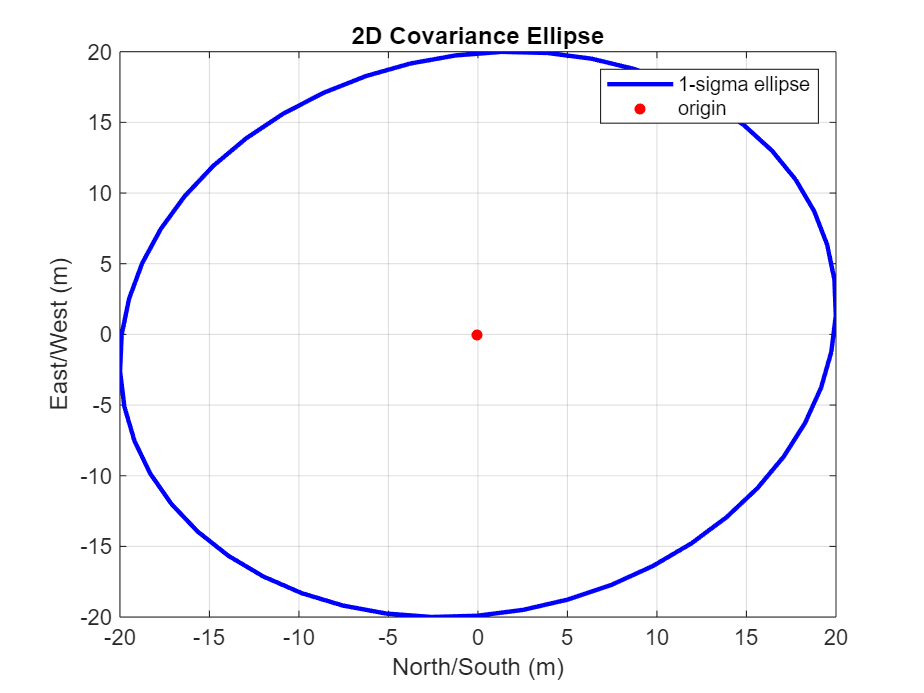

m=[0;0];
[Xe,Ye,U,S,th] = calculate_ellipse(m, P, 1, 50);
figure(1)
plot(Xe,Ye,'b-','linewidth',2);
hold on;
plot(m(1),m(2),'r.','markersize',15);
hold off
legend('1-sigma ellipse','origin');
xlabel('North/South (m)')
ylabel('East/West (m)')
grid;
title('2D Covariance Ellipse');

%view(2)

x = linspace(0,10,500);
y = chi2cdf(x,2);

[E,F] = min(abs(y-0.95))

E = 1.2984e-05

F = 300

x(F)

ans = 5.9920

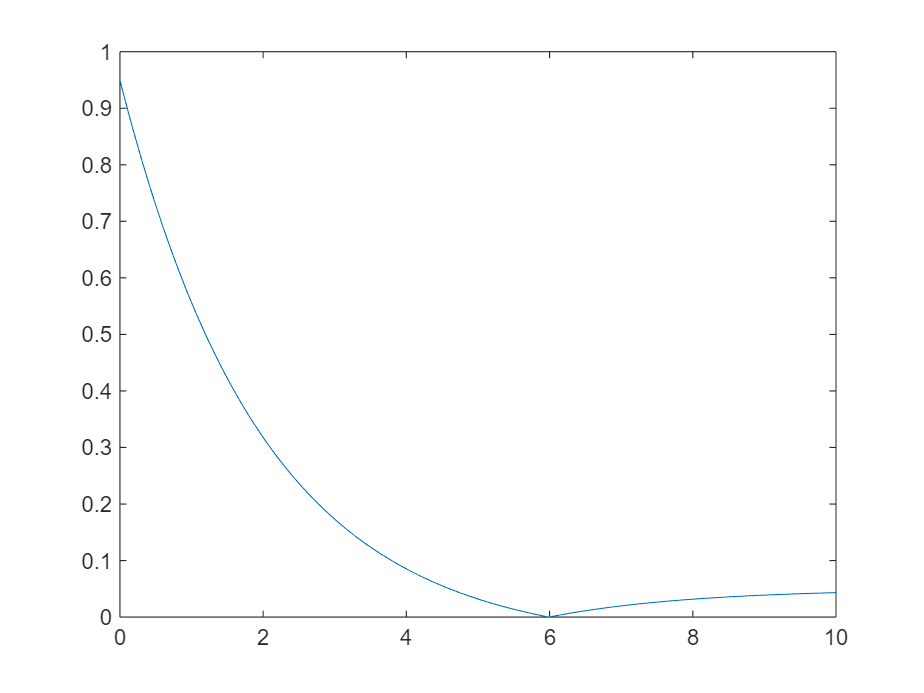


figure(2)
plot(x,abs(y-0.95))

Pinv = inv(P)

Pinv =     0.0025   -0.0003
   -0.0003    0.0025


test = (e_m'*Pinv*e_m)/4

test = 1.9215

test <= 0

ans = logical
   0


## problem 4

%% MAE 6760 Model Based Estimation
%
%   Homework #1
%   problem #4: Linear System driven by Random Processes
%        application: quarter suspension over a bumpy road
%

%constants
M=300;    %car mass (kg)
m=50;     %wheel mass (kg)
K1=3000;  %spring constant (N/m)
K2=30000; %spring constant (N/m)
C1=600;   %damping constant (Nsec/m)

% Set up open loop model, including r,u as inputs and z as output
%
% xdot = A*x + Bu*u + Br*r
%    z = C*x + Du*u + Dr*r
%

%State Space system matrices
A=[0  0  1  0; 
   0  0  0  1 ; 
   -K1/M K1/M -C1/M C1/M ;
   K1/m -(K1+K2)/m C1/m -C1/m];
Bu=[0; 0; 1/M; -1/m];  %The actuator control as an input u(t)
Br=[0; 0; 0; K2/m];   
 %The bumpy road as an input r(t)
C=[1 0 0 0];Du=0;Dr=0; %The driver position as the output
% Bumpy Road white noise disturbance intensity
Sigr = 2E-4; %m^2/sec (NOISE INTENSITY)



%% -------------------
%% Part (a): simulate open loop system
Tf=1000;dt=0.01;t=[0:dt:Tf]';
rng(1)
r=sqrt(Sigr)*randn(length(t),1)/sqrt(dt);

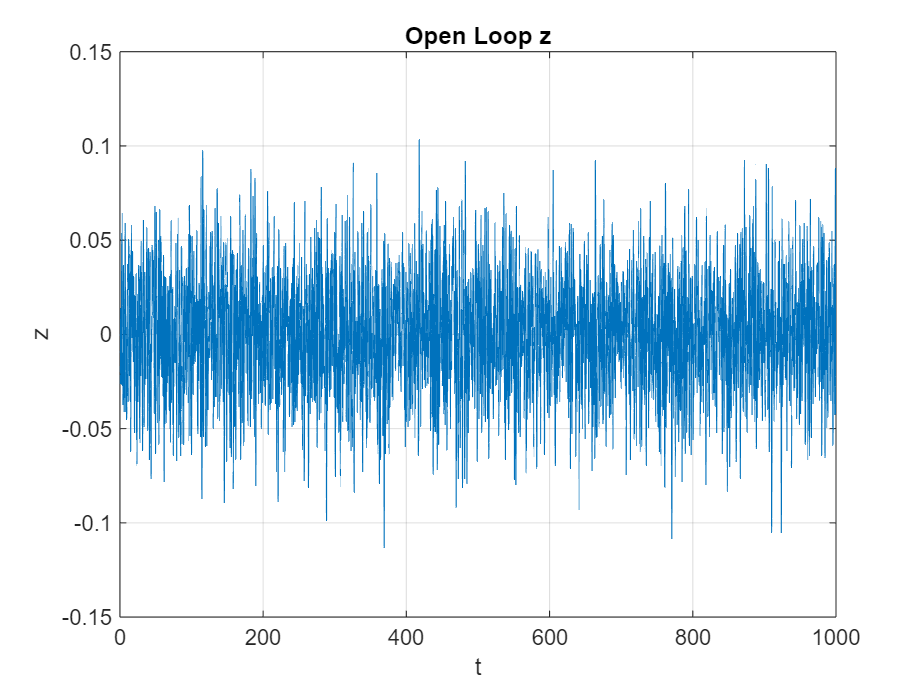

B = [Bu Br];
D = [Du Dr];
sys_object = ss(A,B,C,D);
u = zeros(length(t),1);
U = [u r];
z = lsim(sys_object, U, t);

figure(3)
plot(t,z)
xlabel('t')
ylabel('z')
grid;
title('Open Loop z');

z_cov = cov(z);
disp(['cov:', num2str(z_cov)])

cov:0.00082369



P = lyap(A, Br*Sigr*Br'); 
cov_z_lyap = C * P * C';
disp(['Analytical variance of z: ', num2str(cov_z_lyap)])

Analytical variance of z: 0.00080139



percent_err = abs(z_cov - cov_z_lyap)/cov_z_lyap * 100;

disp(['percent error: ', num2str(percent_err)]);

percent error: 2.7827


%% -------------------
%% Part (b): find and simulate closed loop system
% These lines find the closed loop state feedback controller K,
% where the form of the controller is: u = -K*x
Rzz=1;Ruu=2E-9;
[K,S,E]=lqry(ss(A,Bu,C,Du),Rzz,Ruu);
%
%Simulate the closed loop system for the bumpy road
A_CL = A - Bu*K;
B_CL = [zeros(size(Bu)) Br];

sys_object_CL = ss(A_CL,B_CL,C,D);
[z_CL, tOut, x_CL] = lsim(sys_object_CL, U, t);

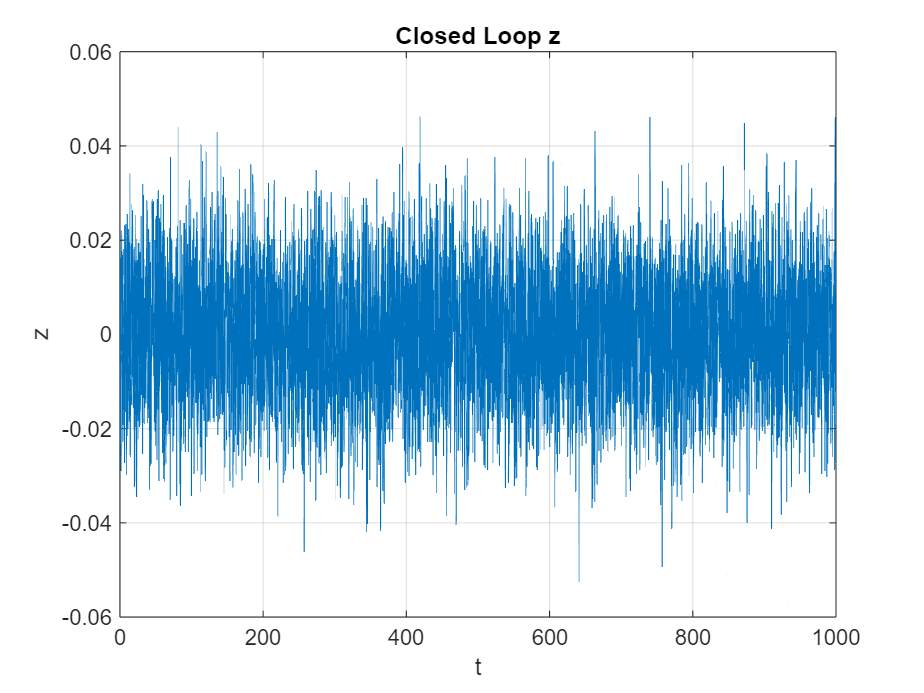

figure(4)
plot(t,z_CL)
xlabel('t')
ylabel('z')
grid;
title('Closed Loop z')


z_cov_CL = cov(z_CL);
disp(['cov:', num2str(z_cov_CL)])

cov:0.00014236



P_CL = lyap(A_CL, Br*Sigr*Br'); 
cov_z_lyap_CL = C * P_CL * C';
disp(['Analytical variance of z: ', num2str(cov_z_lyap_CL)])

Analytical variance of z: 0.00014315



percent_err_CL = abs(z_cov_CL - cov_z_lyap_CL)/cov_z_lyap_CL * 100;

disp(['percent error: ', num2str(percent_err_CL)]);

percent error: 0.54824


cov_z_lyap/cov_z_lyap_CL

ans = 5.5984

std_a_CL = cov_z_lyap_CL^0.5

std_a_CL = 0.0120

std_a_OL = cov_z_lyap^0.5

std_a_OL = 0.0283


std_a_OL- std_a_CL

ans = 0.0163

std_a_OL/ std_a_CL

ans = 2.3661


std_n_CL = z_cov_CL^0.5

std_n_CL = 0.0119

std_n_OL = z_cov^0.5

std_n_OL = 0.0287


%% -------------------
%% Part (c): plot open and closed loop response z(t), analyze

thresh = 0.03 % cm

thresh = 0.0300


P1=normcdf(thresh,0,std_a_OL);
P2=normcdf(thresh, 0, std_a_CL);

2*(1-P1) % probability over 3cm - open loop

ans = 0.2893

2*(1 - P2) % probability over 3cm - closed loop

ans = 0.0122

x_CLT = x_CL'

x_CLT =          0   -0.0000    0.0000    0.0001    0.0001   -0.0001   -0.0006   -0.0013   -0.0024   -0.0036   -0.0048   -0.0061   -0.0073   -0.0084   -0.0094   -0.0102   -0.0107   -0.0111   -0.0116   -0.0121   -0.0124   -0.0124   -0.0120   -0.0110   -0.0095   -0.0074   -0.0052   -0.0030   -0.0009    0.0010    0.0025    0.0037    0.0046    0.0052    0.0057    0.0059    0.0061    0.0063    0.0065    0.0070    0.0076    0.0084    0.0093    0.0101    0.0109    0.0115    0.0119    0.0119    0.0114    0.0104
         0   -0.0001    0.0042    0.0038   -0.0049   -0.0192   -0.0359   -0.0523   -0.0642   -0.0712   -0.0718   -0.0709   -0.0651   -0.0620   -0.0536   -0.0430   -0.0334   -0.0351   -0.0426   -0.0398   -0.0232   -0.0052    0.0165    0.0476    0.0819    0.0989    0.0998    0.0930    0.0867    0.0704    0.0501    0.0358    0.0239    0.0142    0.0049    0.0018    0.0045    0.0081    0.0209    0.0362    0.0463    0.0546    0.0568    0.0550    0.0521    0.0414    0.0248    0.0010   -0.0243 

x_CLT(1,:)

ans =          0   -0.0000    0.0000    0.0001    0.0001   -0.0001   -0.0006   -0.0013   -0.0024   -0.0036   -0.0048   -0.0061   -0.0073   -0.0084   -0.0094   -0.0102   -0.0107   -0.0111   -0.0116   -0.0121   -0.0124   -0.0124   -0.0120   -0.0110   -0.0095   -0.0074   -0.0052   -0.0030   -0.0009    0.0010    0.0025    0.0037    0.0046    0.0052    0.0057    0.0059    0.0061    0.0063    0.0065    0.0070    0.0076    0.0084    0.0093    0.0101    0.0109    0.0115    0.0119    0.0119    0.0114    0.0104


ans =    -0.0000   -0.0000    0.0000    0.0001    0.0001   -0.0001   -0.0006   -0.0013   -0.0024   -0.0036   -0.0048   -0.0061   -0.0073   -0.0084   -0.0094   -0.0102   -0.0107   -0.0111   -0.0116   -0.0121   -0.0124   -0.0124   -0.0120   -0.0110   -0.0095   -0.0074   -0.0052   -0.0030   -0.0009    0.0010    0.0025    0.0037    0.0046    0.0052    0.0057    0.0059    0.0061    0.0063    0.0065    0.0070    0.0076    0.0084    0.0093    0.0101    0.0109    0.0115    0.0119    0.0119    0.0114    0.0104


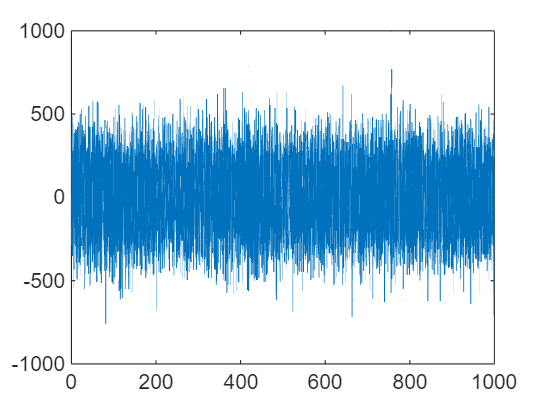



%% -------------------
%% Part (d): analyze the control effort u(t)
[z_CL, tOut, x_CL] = lsim(sys_object_CL, U, t);
u_CL = -x_CL*K';
figure(5)
plot(t,u_CL)

cov_sample_u = cov(u_CL)

cov_sample_u = 2.9796e+04


cov_analytic_u = K*P_CL*K'

cov_analytic_u = 3.1851e+04


abs(cov_sample_u-cov_analytic_u)/cov_analytic_u *100

ans = 6.4536

K

K = 1.0e+04 *

    1.9561   -0.5456    0.3366    0.0094
